# Classify Product Reviews Using Convolutional Neural Network

To classify text data using Convolutional Neural Network, the text must be converted to image. Reviews are padded or truncated to a constant length *S* and then converted into sequences of word vectors of length *C* using a word embedding. The reviews are now represented as 1-by-*S*-by-*C* image - an image with height 1, width *S*, and *C* depth.

This code trains a network with 1-D convolutional filters of varying widths. The width of each filter corresponds to an n-gram length of words. The network has multiple branches of convolutional layers, so it can use different n-gram lengths. 

clear all % clear variables from workspace

**HYPERPARAMETER FOR TUNING**

sql = 128;          % sequence length
nf = 256;           % number of filters
ngl = [2 3 4 5];    % ngramlengths
mbs = 1024;         % mini batch size
me = 50;            % maximum number of epochs during training
ilr = 0.01;         % initial learning rate
vf = 1;             % training validation frequency
do = 0.0;           % drop out probability for drop out layer
str = [1 1];        % define filter stride for convolution filtering
gdf = 0.9;          % set gradient decay factor for use in training options
sgdf = 0.9;         % set value for squared gradient factor for use in training options
p = 0.1;            % set pecentage of holdout data for training validation
lrdf = 0.5;         % learn rate drop factor
lrdp = 5;           % learn rate drop period - every 10 epochs
l2r = 0.0005;       % regularization to limit overfitting


## Load Pretrained Word Embedding

Load the pretrained fastText word embedding. Model *for fastText English 16 Billion Token Word Embedding* 

emb = fastTextWordEmbedding;

## Load Data

Read the data from the `"comments text"` and `"labeled"` columns only.

ReadTrain = "Furniture_Train.csv";
data = readtable(ReadTrain,"VariableNamingRule","preserve");

TRAINING AND VALIDATION

% Read the labels from the data and find the unique class names.

% Categorize data labels
DataLabels = data{:, "HumanSentiment"};
classNames = unique(DataLabels);
DataLabels_Categorical = categorical(DataLabels,classNames);

% Extract text of reviews
ReviewText = data{:, "ReviewText"};

## Preprocess Text

% Tokenize the text.
documents = tokenizedDocument(ReviewText);

% Convert the text to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove tokens containing digits.
pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
documents = replace(documents,pat,"");

% Stem and lemmatize
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Fix mis-spelled words
documents = correctSpelling(documents);

% Remove 1 character words
documents = removeShortWords(documents, 1)

documents =   4762×1 tokenizedDocument:

     22 tokens: get down put last drawer together find manufacturer drill hole incorrectly drawer side late send back drawer tacky need item week ago
      6 tokens: beautiful perfect size love great price
     76 tokens: even bad review decide go against gut purchase dresser grant cheap tax come around put almost dresser together notice drawer side miss tempt take dresser back whole part get replacement hopefully part need package specify miss part contact company try replacement part order online luck keep tell part incorrect way stupid call number type still wait hold minute feel like wait IRS cheap dresser save purchase expensive may well purchase same price try true another consumer
      1 tokens: OK
     11 tokens: everything say start day old daughter extra sheet support back love
     29 tokens: return item work baby insert really change feel halo baby expect rest

Prepare documents for sizing to fit CNN

Converts data into a table containing the predictors and the responses. The predictors are 1-by-`sequenceLength`-by-*C* arrays of word vectors given by the word embedding `emb`, where *C* is the embedding dimension. The responses are categorical labels over the classes in `classNames`.

% Convert documents to embeddingDimension-by-sequenceLength-by-1 images.
sequenceLength = sql;
predictors = doc2sequence(emb,documents,'Length',sql, "UnknownWord","discard","PaddingDirection","right")

predictors = 4762×1 cell array
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}


APPLY SMOTE

% Oversample "SAFETY ISSUES" class
XTTvectors = predictors;
embVocabVectors = word2vec(emb, emb.Vocabulary);
XLL = DataLabels_Categorical;

idxS = DataLabels_Categorical=='SAFETY ISSUES';
XTTs = XTTvectors(idxS, :);

NN = sum(DataLabels_Categorical=='NO ISSUES')

NN = 2793

QQ = sum(DataLabels_Categorical=='QUALITY ISSUES')

QQ = 1750

SS = sum(DataLabels_Categorical=='SAFETY ISSUES')

SS = 219

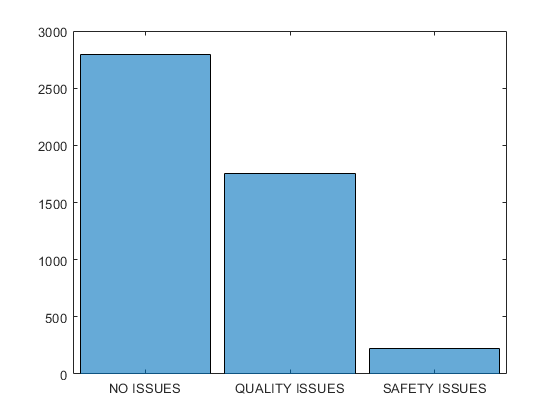

histogram(DataLabels_Categorical)


S2N = floor(2*NN/SS)

S2N = 25

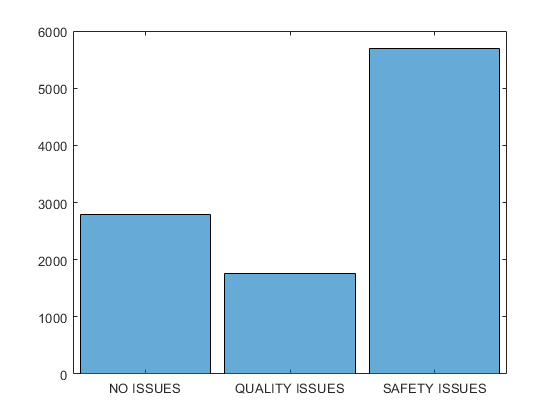


DataLabelsNew = categorical.empty();

for ll = 1:S2N
    for kk = 1:SS
        XTTcell = XTTs{kk};
        XTTcell = transpose(XTTcell);
        idxxx = knnsearch(embVocabVectors,XTTcell(ll,:),"K",2);
        
        XTTcell(ll,:) = embVocabVectors(idxxx(2), :);  
        XTTsNew{1} = transpose(XTTcell);
        
        XTTvectors = [XTTvectors; XTTsNew];
        DataLabelsNew(ll,kk) = 'SAFETY ISSUES';
    end        
end

DataLabelsNew = reshape(DataLabelsNew, S2N*SS, 1);
DataLabels_Categorical = [DataLabels_Categorical; DataLabelsNew];

histogram(DataLabels_Categorical)

% Oversample "QUALITY ISSUES" class
idxQ = DataLabels_Categorical=='QUALITY ISSUES';
XTTq = XTTvectors(idxQ, :);

Q2N = floor(1.2*NN/QQ)

Q2N = 1

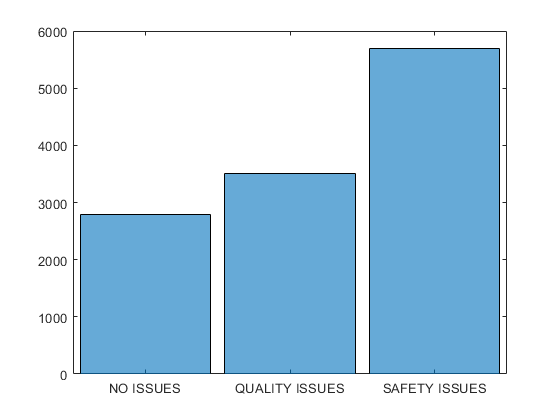


DataLabelsNewQ = categorical.empty();

for ll = 1:Q2N
    for kk = 1:QQ
        XTTcellQ = XTTq{kk};
        XTTcellQ = transpose(XTTcellQ);
        idxxx = knnsearch(embVocabVectors,XTTcellQ(ll,:),"K",2);
        
        XTTcellQ(ll,:) = embVocabVectors(idxxx(2), :);  
        XTTqNew{1} = transpose(XTTcellQ);
        
        XTTvectors = [XTTvectors; XTTqNew];
        DataLabelsNewQ(ll,kk) = 'QUALITY ISSUES';
    end        
end

DataLabelsNewQ = reshape(DataLabelsNewQ, Q2N*QQ, 1);
DataLabels_Categorical = [DataLabels_Categorical; DataLabelsNewQ];

histogram(DataLabels_Categorical)


predictors = XTTvectors;

numObservations = numel(DataLabels_Categorical);

% Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
predictors = cellfun(@(X) permute(X,[3 2 1]),predictors,'UniformOutput',false);

Partition data

C1 = DataLabels_Categorical;

Data_PreProcessed = table;
Data_PreProcessed.Predictors = predictors;
Data_PreProcessed.Responses = C1;

cvp = cvpartition(Data_PreProcessed.Responses,'Holdout',p);
dataValidation = Data_PreProcessed(test(cvp),:);
dataTrain = Data_PreProcessed(training(cvp),:);

## Define Network Architecture

Define the network architecture for the classification task.

The following steps describe the network architecture.

- Specify an input size of 1-by-*S*-by-*C*, where *S* is the sequence length and *C* is the number of features (the embedding dimension).

- For the n-gram lengths 2, 3, 4, and 5, create blocks of layers containing a convolutional layer, a batch normalization layer, a ReLU layer, a dropout layer, and a max pooling layer.

- For each block, specify nf convolutional filters of size 1-by-*N* and pooling regions of size 1-by-*S*, where *N* is the n-gram length.

- Connect the input layer to each block and concatenate the outputs of the blocks using a depth concatenation layer.

- To classify the outputs, include a fully connected layer with output size *K*, a softmax layer, and a classification layer, where *K* is the number of classes.

First, in a layer array, specify the input layer, the first block for unigrams, the depth concatenation layer, the fully connected layer, the softmax layer, and the classification layer.

numFeatures = emb.Dimension;
inputSize = [1 sql numFeatures];

numBlocks = numel(ngl);

numClasses = numel(classNames);

Create a layer graph containing the input layer. Set the normalization option to `'none'` and the layer name to `'input'`.

layer = imageInputLayer(inputSize,'Normalization','none','Name','input'); %what does setting the ormalization to none do?
lgraph = layerGraph(layer);

For each of the n-gram lengths, create a block of convolution, batch normalization, ReLU, dropout, and max pooling layers. Connect each block to the input layer.

for j = 1:numBlocks
    N = ngl(j);
    
    block = [
        convolution2dLayer([1 N],nf,'Name',"conv"+N,...
                            'Padding','same',...
                            "WeightsInitializer","he",...
                            "Stride",str,...
                            "BiasInitializer","narrow-normal")
        batchNormalizationLayer('Name',"bn"+N)
        reluLayer('Name',"relu"+N)
        dropoutLayer(do,'Name',"drop"+N)
        maxPooling2dLayer([1 sql],'Name',"max"+N)];
    
    lgraph = addLayers(lgraph,block);
    lgraph = connectLayers(lgraph,'input',"conv"+N);
end

View the network architecture in a plot.

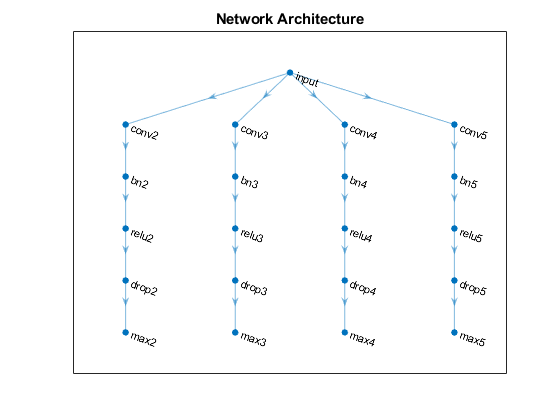

figure
plot(lgraph)
title("Network Architecture")

Add the depth concatenation layer, the fully connected layer, the softmax layer, and the classification layer. 

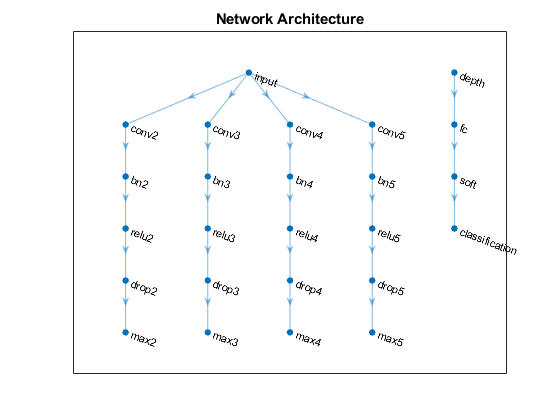

layers = [
    depthConcatenationLayer(numBlocks,'Name','depth')
    fullyConnectedLayer(numClasses,'Name','fc',"WeightsInitializer","he")
    softmaxLayer('Name','soft')
    classificationLayer('Name','classification')];
    %weightedClassificationLayer(classWeights, 'classification')]

lgraph = addLayers(lgraph,layers);

figure
plot(lgraph)
title("Network Architecture")

Connect the max pooling layers to the depth concatenation layer and view the final network architecture in a plot.

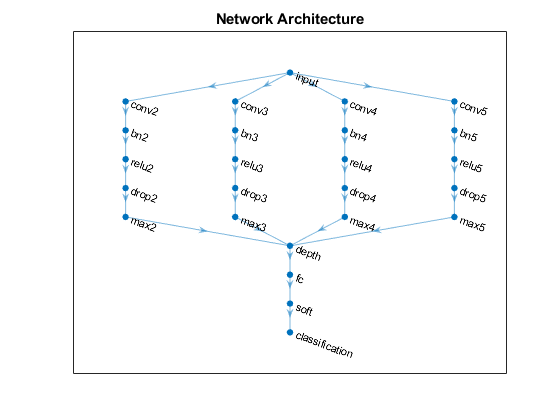

for j = 1:numBlocks
    N = ngl(j);
    lgraph = connectLayers(lgraph,"max"+N,"depth/in"+j);
end

figure
plot(lgraph)
title("Network Architecture")

## Train Network

Specify the training options:

- Train with a mini-batch size of mbs

- Shuffle the data every vf epochs.

- Display the training progress plot and suppress the verbose output.

Define training options

numIterationsPerEpoch = floor(numObservations/mbs);

options = trainingOptions('adam', ... 
    'MiniBatchSize',1024, ...
    'Shuffle','every-epoch', ... 
    'GradientDecayFactor', gdf, ...
    'SquaredGradientDecayFactor', sgdf, ...
    'MaxEpochs', 15, ...
    'Plots','training-progress', ...
    'InitialLearnRate', 0.05, ... 
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', lrdp, ...
    "ValidationData",dataValidation, ...
    "ValidationFrequency",vf, ...
    "L2Regularization", 0.05, ...
    "LearnRateSchedule","piecewise", ...
    'Verbose',false); 

Train the network using the `trainNetwork` function.

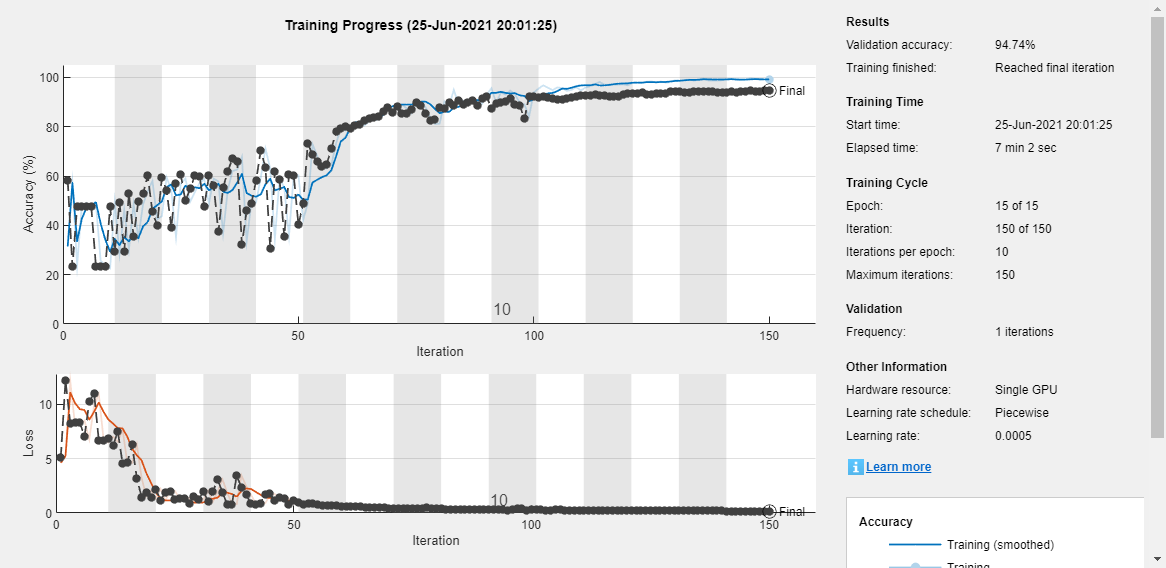

net = trainNetwork(dataTrain,lgraph,options);

## Predict Using New Data

Create a table containing the test reviews.

ReadTest = "Furniture_Test.csv";
DataTest = readtable(ReadTest,"VariableNamingRule","preserve");
ReviewsTest = DataTest{:, "ReviewText"}

ReviewsTest = 545×1 cell array
    {'Great product easy to put together all by myself.'                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 


filenameWriteCheck = 'DataTestCheck.xlsx';
writetable(DataTest,filenameWriteCheck);

## Preprocess Text

% Tokenize the text.
documents = tokenizedDocument(ReviewsTest);

% Convert the text to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove tokens containing digits.
pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
documents = replace(documents,pat,"");

% Stem and lemmatize
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Fix mis-spelled words
documents = correctSpelling(documents);

% Remove 1 character words
documents = removeShortWords(documents, 1)

documents =   545×1 tokenizedDocument:

      6 tokens: great product easy put together myself
      5 tokens: toddler love chair great value
     10 tokens: price get good drawer stick time sturdy go wrong price
     49 tokens: new granddaughter love bouncer able assemble minimum effort instruction clear activity bar high young baby able supplement low activity bar previous small bouncer replace same company disappoint mirror activity bar old bouncer plenty room grow eventually able bat high bar enjoy colorful object dexterity improve pleased naans sweet pea
      5 tokens: absolutely recommend durable meet expectation
     35 tokens: fall love look little rocking seat disappointed find doesn't automatically rock just vibrate old style little weighted piece back gently bounce press button manually rock seat color perfect gender cushion super comfy plush why star
     14 tokens: love give time new mother love won


% Convert documents to embeddingDimension-by-sequenceLength-by-1 images.
% documents = doc2sequence(emb,documents,'Length',sql);
documents = doc2sequence(emb,documents,'Length',sql, "UnknownWord","discard","PaddingDirection","right")

documents = 545×1 cell array
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}




% Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
documents = cellfun(@(X) permute(X,[3 2 1]),documents,'UniformOutput',false);


Classify the new sequences using the trained Convolutional Neural Network.

XNew = table;
XNew.Predictors = documents;
labelsNew = classify(net,XNew);

Check Accuracy

labelsTrue = categorical(DataTest{:, "HumanSentiment"});
AccuracyCNN = sum(labelsTrue == labelsNew)/numel(labelsTrue == labelsNew)

AccuracyCNN = 0.7615

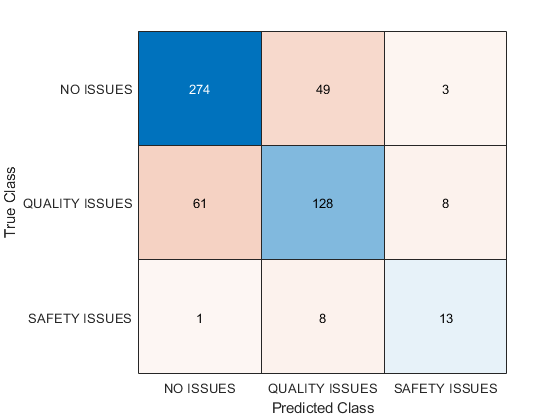

confusionchart(labelsTrue, labelsNew)


DataTest.Predictions = labelsNew;
filenameWrite = 'TroubleshootTest2.xlsx';
writetable(DataTest,filenameWrite);

Investigate model statistics

- Precision=TP / (TP + FP)

- Recall= TP / (TP + FN)

- F-score = 2*TP /(2*TP+ FP + FN)

- Accuracy = (TP + TN) / (TP + FP + TN + FN)

- False Positive – Type 1 Error

- False Negative – Type 2 Error

cm = confusionmat(labelsTrue, labelsNew)

cm =    274    49     3
    61   128     8
     1     8    13



NTP = cm(1);
NFP = cm(2) + cm(3);
NTN = cm(5) + cm(6) + cm(8) + cm(9);
NFN = cm(4) + cm(7);

QTP = cm(5);
QFP = cm(4) + cm(6);
QTN = cm(1) + cm(3) + cm(7) + cm(9);
QFN = cm(2) + cm(8);

STP = cm(9);
SFP = cm(7) + cm(8);
STN = cm(1) + cm(2) + cm(4) + cm(5);
SFN = cm(3) + cm(6);

accuracy_cm = [(NTP+NTN)/(NTP+NTN+NFP+NFN); (QTP+QTN)/(QTP+QTN+QFP+QFN); (STP+STN)/(STP+STN+SFP+SFN)]

accuracy_cm =     0.7908
    0.7688
    0.9633


overall_accuracy = mean(accuracy_cm)

overall_accuracy = 0.8410


precision_cm = [NTP/(NTP+NFP); QTP/(QTP+QFP); STP/(STP+SFP)]

precision_cm =     0.8155
    0.6919
    0.5417


overall_precision = mean(precision_cm)

overall_precision = 0.6830


recall_cm = [NTP/(NTP+NFN); QTP/(QTP+QFN); STP/(STP+SFN)]

recall_cm =     0.8405
    0.6497
    0.5909


overall_recall = mean(recall_cm)   

overall_recall = 0.6937


fscore_cm = [2*NTP /(2*NTP+ NFP + NFN); 2*QTP /(2*QTP+ QFP + QFN); 2*STP /(2*STP+ SFP + SFN)]

fscore_cm =     0.8278
    0.6702
    0.5652


overall_fscore = mean(fscore_cm)

overall_fscore = 0.6877


[accuracy_cm precision_cm recall_cm fscore_cm; overall_accuracy overall_precision overall_recall overall_fscore]

ans =     0.7908    0.8155    0.8405    0.8278
    0.7688    0.6919    0.6497    0.6702
    0.9633    0.5417    0.5909    0.5652
    0.8410    0.6830    0.6937    0.6877


## Preprocess Reviews Function

The `preprocessReviews `function takes text data from the reviews, and processes it to a form that is suitable for machine operations.

The `PreProcesedReviews` function takes text data and performs these steps:

- Tokenize the text.

- Convert the text to lowercase.

- Erase punctuation

- Remove tokens containing digits

- Stem and lemmatize

- Fix mis-spelled words

- Remove 1 character words

function PreProcesedReviews = preprocessReviews(ReviewText)

    % Tokenize the text.
    documents = tokenizedDocument(ReviewText);
    
    % Convert the text to lowercase.
    documents = lower(documents);
    
    % Erase punctuation.
    documents = erasePunctuation(documents);
    
    % Remove tokens containing digits.
    pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
    documents = replace(documents,pat,"");
    
    % Stem and lemmatize
    documents = addPartOfSpeechDetails(documents);
    documents = removeStopWords(documents);
    documents = normalizeWords(documents,'Style','lemma');
    
    % Fix mis-spelled words
    documents = correctSpelling(documents);
    
    % Remove 1 character words
    documents = removeShortWords(documents, 1);
    
    % Assign function output
    PreProcesedReviews = documents;
end